clear

addpath('functions\')

#### Compute $\Phi$

Model = myModel;

freqs = [1000 2000 4000 16000]; % (Hz)

freqs = reshape(freqs, 1,1,[]);
M = size(Model.sensors.positions,2);
N = size(Model.voxels.center,2);
Phi = zeros(M, N, length(freqs));

for k = 1:length(freqs)
    tic
    S_sigma = Model.Sensitivity(freqs(k));
    Phi(:,:,k) = -S_sigma .* Model.voxels.sigma;
    fprintf('Compute %g Hz sensitivity took %.2f seconds\n', freqs(k), toc)
end

Compute 1000 Hz sensitivity took 44.75 seconds
Compute 2000 Hz sensitivity took 4.02 seconds
Compute 4000 Hz sensitivity took 3.99 seconds
Compute 16000 Hz sensitivity took 4.04 seconds


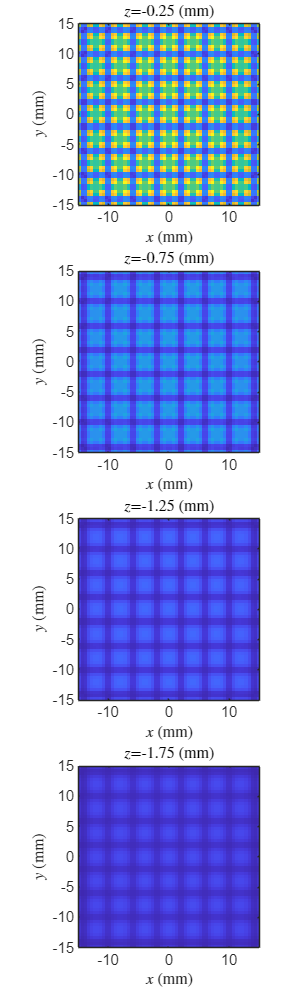


voxels_center = Model.voxels.center;

fname = sprintf('data/Phi_%s.mat', datetime('now','Format','MMdd-HHmm'));
save(fname, 'freqs','Phi','voxels_center', "-v7.3");


plot_sensitivity(fname)